# Lab 4: Haar Wavelets

clear
addpath('resources', 'scripts');

## Question 4.1

x = [1 4 2 3 1 0 0 2];

h0 = [1/sqrt(2) 1/sqrt(2)];
h1 = [-1/sqrt(2) 1/sqrt(2)];

[a,b] = dwlt(x, h0, h1);

% Conservation of energy if e1 = e2:
e1 = sum(x.^2);
e2 = sum(a.^2)+sum(b.^2);

## Question 4.2

x2 = idwlt(a,b,h0,h1);

## Question 4.3

x3 = wldecom(x,3,h0,h1);

## Question 4.4

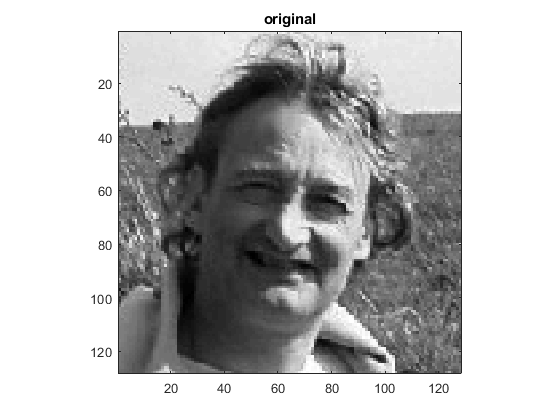

clear
load("ronald.mat");

h0 = [1/sqrt(2) 1/sqrt(2)];
h1 = [-1/sqrt(2) 1/sqrt(2)]; % ### different order of minus?

figure(1)
imagesc(ronald)
colormap gray
axis image
title('original')

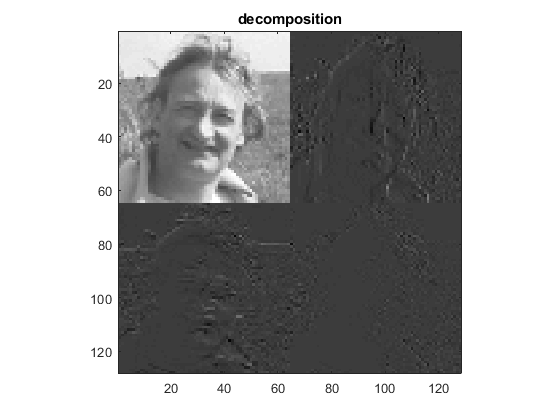


figure(2)
ronald_haar = dwlt2D(ronald,h0,h1);
imagesc(ronald_haar)
colormap gray
axis image
title('decomposition')

## Question 4.5

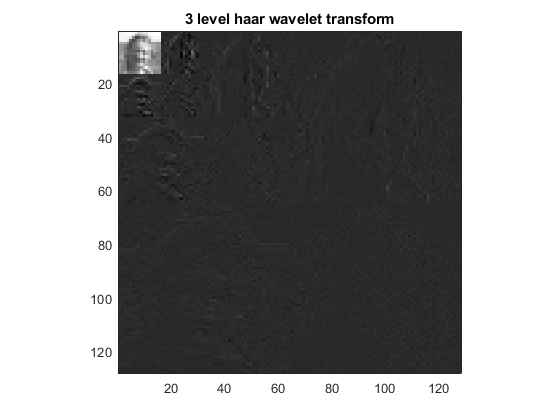

[~,A1,V1,H1,D1] = dwlt2D(ronald,h0,h1);
[~,A2,V2,H2,D2] = dwlt2D(A1,h0,h1);
haar3 = dwlt2D(A2,h0,h1);

ronald_3haar = [[haar3,V2;H2,D2],V1;H1,D1];

figure(3)
imagesc(ronald_3haar)
colormap gray
axis image
title('3 level haar wavelet transform')

## Question 4.6

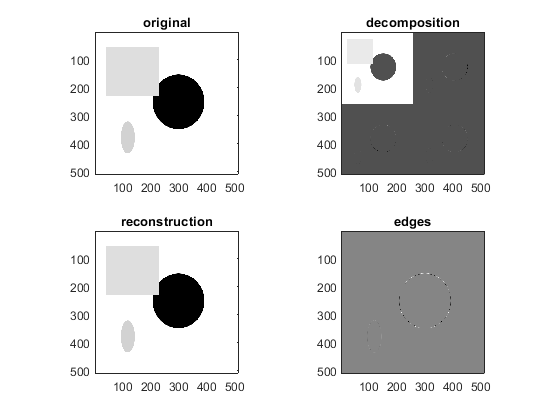

clear

im = imread('foo.png');

h0 = [1/sqrt(2),1/sqrt(2)];
h1 = [-1/sqrt(2),1/sqrt(2)];

[im_haar,A,V,H,D] = dwlt2D(im,h0,h1);
im_haar_r = idwlt2D(h0,h1,im_haar);
im_edges = idwlt2D(h0,h1,zeros(size(im)/2),V,H,D);

figure(4)
subplot(2,2,1)
imagesc(im)
colormap gray
axis image
title('original')
subplot(2,2,2)
imagesc(im_haar)
colormap gray
axis image
title('decomposition')
subplot(2,2,3)
imagesc(im_haar_r)
colormap gray
axis image
title('reconstruction')
subplot(2,2,4)
imagesc(im_edges)
colormap gray
axis image
title('edges')

## Question 4.7

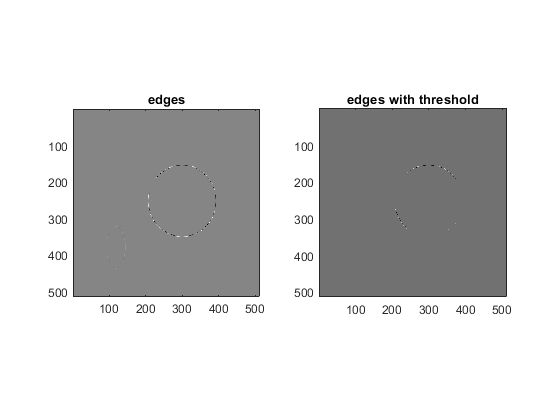

tau = 100;
V_thr = threshold(V,tau);
H_thr = threshold(H,tau);
D_thr = threshold(D,tau);
im_edges_thr = idwlt2D(h0,h1,zeros(size(im)/2),V_thr,H_thr,D_thr);

figure(5)
subplot(1,2,1)
imagesc(im_edges)
colormap gray
axis image
title('edges')
subplot(1,2,2)
imagesc(im_edges_thr)
colormap gray
axis image
title('edges with threshold')

## Question 4.8

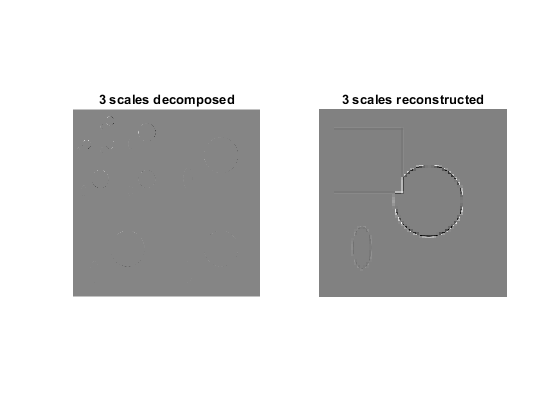

clear
im = imread('foo.png');

h0 = [1/sqrt(2),1/sqrt(2)];
h1 = [-1/sqrt(2),1/sqrt(2)];

[~,A1,V1,H1,D1] = dwlt2D(im,h0,h1);
[~,A2,V2,H2,D2] = dwlt2D(A1,h0,h1);
[Y3,A3,V3,H3,D3] = dwlt2D(A2,h0,h1);

im_3haar = [[[zeros(size(im)/8),V3;H3,D3],V2;H2,D2],V1;H1,D1];

im_1haar_r = idwlt2D(h0,h1,zeros(size(im)/8),V3,H3,D3);
im_2haar_r = idwlt2D(h0,h1,im_1haar_r,V2,H2,D2);
im_3haar_r = idwlt2D(h0,h1,im_2haar_r,V1,H1,D1);

figure(6)
subplot(1,2,1)
imagesc(im_3haar)
colormap gray
axis image off
title('3 scales decomposed')
subplot(1,2,2)
imagesc(im_3haar_r)
colormap gray
axis image off
title('3 scales reconstructed')

## Question 4.9

clear
load('data2_1.mat')
fs = 15.5;
X1 = fft(x);
f=linspace(0,fs,length(X1)+1);f(end)=[];

## Question 4.10

## Question 4.11